# Projetos no domínio da frequência 

# Projeto do controlador PID

Este live script  apresenta e discute os projetos de controladores PI, PD e PID no domínio  da frequência, usando gráficos de Bode.

De forma similar ao projetos dos compensadores avanço e atraso, busca-se aumentar a margem de fase de forma a tornar a  resposta menos oscilatória, e ao mesmo tempo com resposta rápida.

Seja o controlador PID dado por

A parte proporcional do controlador PD é feita igual a 1, $K_{P1}=1,$  uma vez que o controlador PID tem apenas 3 parâmetros.

Equacionando os dois lados do sinal de igualdade vem,


$$K_P=K_{P2}+K_{D1}K_{I2}$$



$$K_D=K_{D1}K_{P2}$$



$$K_I=K_{I2}$$


Pode-se assim fazer o projeto separado do PI e do PD, e depois unir seus efeitos.

## **Definição do modelo e especificações de projeto**. 

Seja a FT de MA $G(s)=\frac{K}{(1+T_1s)(1+T_2s)}$, assumindo os parâmetros abaixo: 

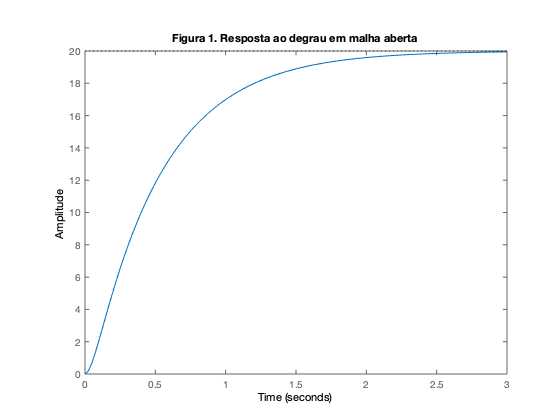

K=20;
T1=0.5;
T2=0.05;
G=tf(K,conv([T1 1],[T2 1]));
figure;step(G);
title('Figura 1. Resposta ao degrau em malha aberta');

Especificações de projeto:

- Erro em regime $\le$1%

- Tempo de estabelecimento $\le$1 segundo.

- Sobreelevação $\le$4%, o que corresponde a $\zeta\geq 0.7$.

A resposta deste modelo será dada pelo modelo de referência $M(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}=\frac{32.6}{s^2+8.96s+32.6}$

Faremos primeiro o projeto do controlador PI, para atender as especificações de erro em regime e tempo de estabelecimento. 

O controlador PD será adicionado depois para reduzir a sobreelevação.

## Projeto do controlador PI via gráfico de Bode

Seja $G_c(s)=K_p+\frac{K_i}{s}=K_p\frac{s+\frac{K_i}{K_p}}{s}=K_i\frac{1+\frac{K_p}{K_i}s}{s}$.

Este controlador aumenta o tipo do sistema ao adicionar um polo na origem. Portanto, o erro à entrada degrau é nulo em qualquer sistema que usa o controlador PI.

Analisando o gráfico de Bode deste controlador para $s=j\omega$, vem

$G_c(j\omega)=K_i\frac{1+\frac{K_p}{K_i}j\omega}{j\omega}$.

Uma década antes do zero, ou seja, em $\omega=\frac{K_i}{10K_p}$, o módulo é dado por 


$$\frac{K_i}{\omega}=\frac{K_i}{\frac{K_i}{10K_p}}=10K_p$$


Em $\omega=\frac{K_i}{K_p}$, o módulo é dado por $K_p$. Isso é mostrado no gráfico de módulo abaixo.

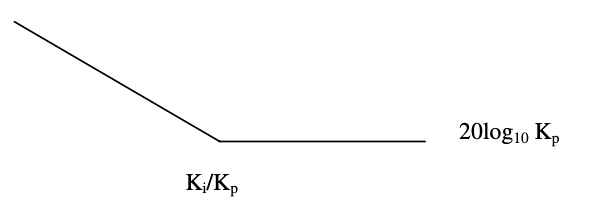			

Da mesma forma, a fase devida ao controlador será de $-90^o$ uma década antes de $\frac{K_i}{K_p}$, $-45^o$  em  $\frac{K_i}{K_p}$  e $0^o$ em $10\frac{K_i}{K_p}$, como mostrado na figura abaixo. 

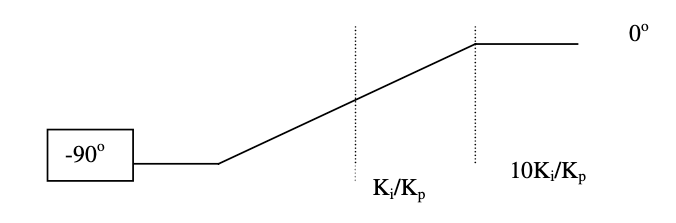					

**Como usar o controlador PI para aumentar a margem de fase? **

Seja o sistema hipotético mostrado abaixo. 

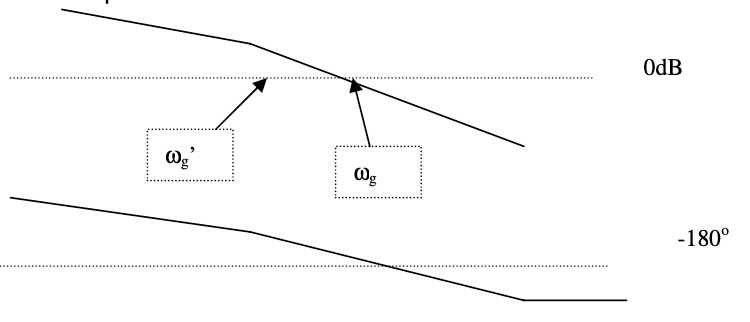			

Observe que se o módulo de G(s) cruzasse em 0dB em $\omega_g^{'}$, a MF seria maior. Para que isto aconteça, basta escolher $K_p<1$ para abaixar a curva de módulo. Assim, escolhendo $K_p$ tal que 

$|G(j\omega_g^{'})|+20log_{10}K_p=0$    ou   $K_p=10^{-\frac{|G(j\omega_g^{'})|}{20}}$

o módulo da curva compensada cruzará em 0dB na nova freqüência $\omega_g^{'}$.

Falta agora obter o valor de $K_i$.

Observando a curva de fase do controlador, vemos que na freqüência $10\frac{K_i}{K_p}$ a fase devida ao controlador é zero graus.  Assim, escolhendo $10\frac{K_i}{K_p}=\omega_g^{'}$, a curva compensada de fase não sofrerá alteração na freqüência $\omega_g^{'}$, onde queremos nossa nova e maior margem de fase. 

Seja como exemplo o gráfico de Bode de G(s).

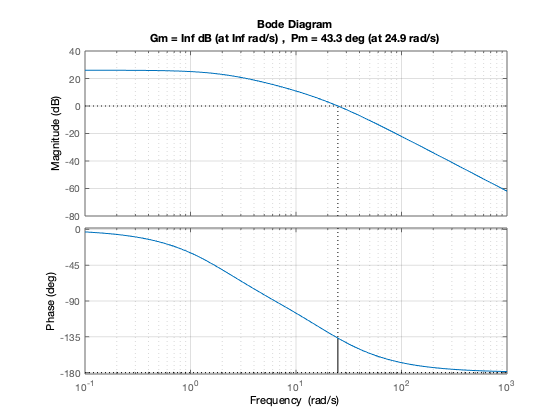

figure;margin(G);grid;

A margem de fase é 43 graus. Suponha que se queira aumentar para 74 graus. Para isto, a curva de módulo deve cruzar por 0 dB em $\omega_g^{'}=10rad/s$, implicando em uma reducão do módulo de 13dB. Usando a expressão $K_p=10^{-\frac{|G(j\omega_g^{'})|}{20}}$, $K_p=10^{-\frac{13}{20}}=0.22$		

O zero do PI em $s=-\frac{K_i}{K_p}$ deve ser colocado uma década antes de $\omega_g^{'}$, portanto em $1rad/s$, de modo que em $\omega=10rad/s$ o efeito do atraso de fase do controlador já tenha desaparecido. Portanto, $K_i=\frac{10}{10}K_p=0.22$

O gráfico abaixo mostra a compensação feita, em que a margem de fase passou de 43 para 74 graus.

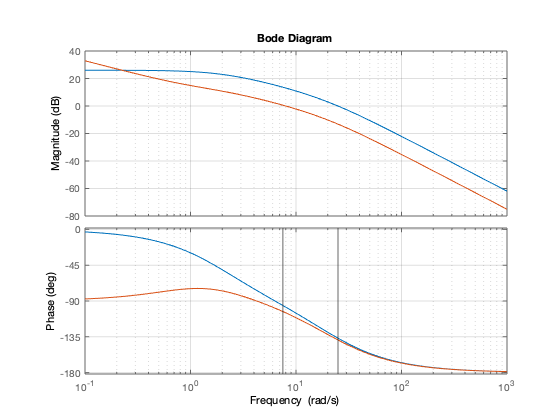

Kp=0.22;
Ki=0.22;
c1=tf([Kp Ki],[1 0]);
figure;
bode(G,c1*G);grid;xline(25);xline(7.5);

Vamos analisar agora a resposta ao degrau para esse controlador:

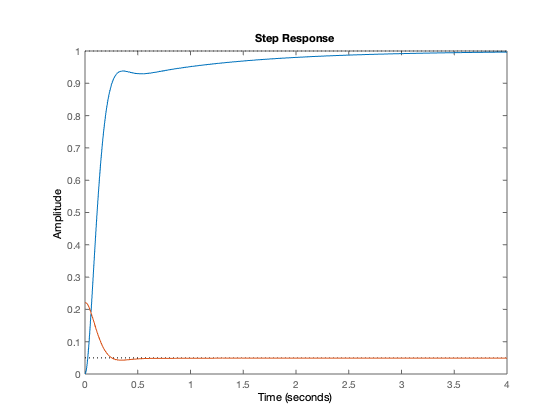

m=feedback(c1*G,1);
mu=feedback(c1,G);
figure;step(m,mu);

Observe que a resposta ficou lenta, com tempo de estabelecimento muito maior do que o especificado.

Uma alternativa é escolher uma margem de fase menor. A outra, é usar um controlador PD.

Neste caso, o controlador PI pode ser usado para atender o erro em regime e reduzir o tempo de estabelecimento, aumentando o ganho $K_p$. Neste caso, $K_p$ é aumentado e $K_i$ é escolhido da mesma forma,$\frac{K_i}{K_p}=\frac{\omega_g^{'}}{10}$.

Seja $K_p=2,$e abaixo o gráfico de Bode compensado com este ganho, que cruza por 0 dB na frequência 40rad/s. O zero do PI deve ser colocado uma década antes, ou seja em 4rad/s. Logo, $K_i=\frac{40}{10}Kp=8$. Veja como fica a compensação.

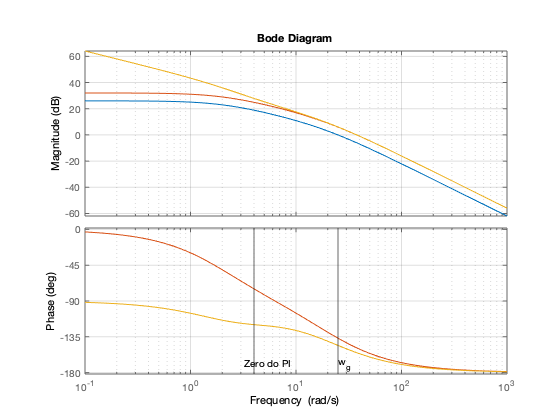

Kp=2;
Ki=8;
c1=tf([Kp Ki],[1 0]);
bode(G,Kp*G,c1*G);grid
xline(25);xline(8/2);text(3,-168,' Zero do PI');text(25,-168,'w_g');

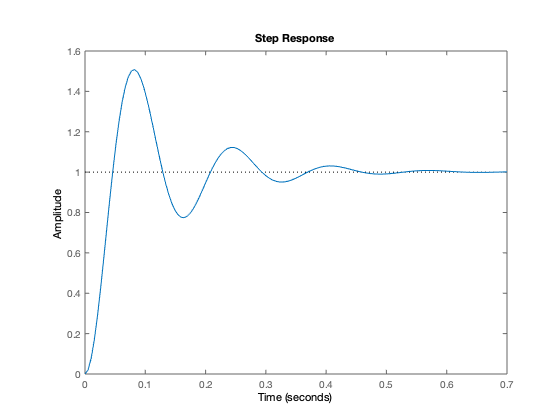

m1=feedback(c1*G,1);
figure;step(m1);

A resposta agora está muito mais rápida, porém com sobreelevação.

Trata-se, de um bom momento para discutir o projeto do controlador PD, que pode reduzir esta sobreelevação.

**Antes, vamos discutir o uso da função projpi.**

Esta função automatiza os passos acima. Os argumentos são a FT de MA g e o ganho m que se quer adicionar ou retirar, em dB.

Sem argumentos de saída, mostra-se o gráfico de Bode e a resposta ao degrau.

Seja o primeiro caso, em que ser quer retirar 13dB.

[c, wg]  = projpi( G, -13)


c =
 
  0.2239 s + 0.1789
  -----------------
          s
 
Continuous-time transfer function.



wg = 7.9895

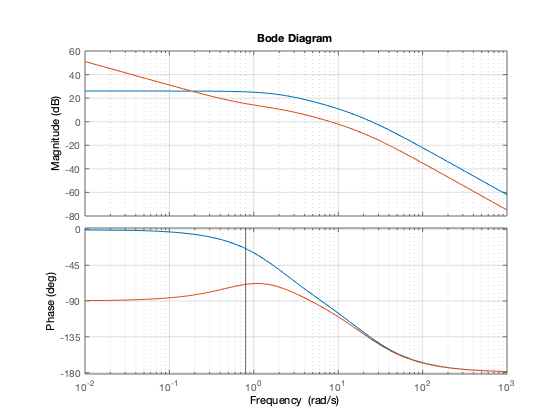

figure;bode(G,c*G);grid;xline(wg/10);

Seja agora o segundo caso, em que deseja aumentar o ganho $K_p$ para 2, ou seja 6dB;

[c, wg]  = projpi( G, 6)


c =
 
  1.995 s + 6.478
  ---------------
         s
 
Continuous-time transfer function.



wg = 32.4688

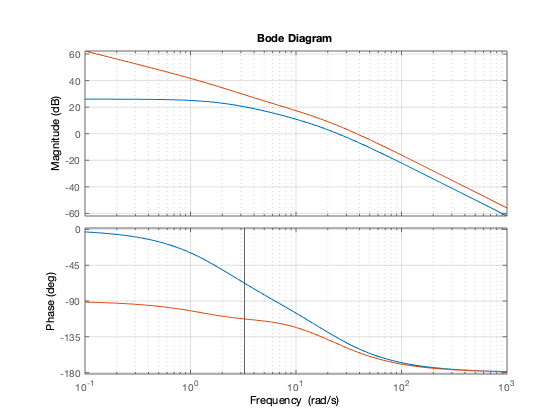

figure;bode(G,c*G);grid;xline(wg/10);

Na linha de comando, pode-se escolher vários valores de ganho, por exemplo projpi(G,[-13  -5   6]), resultando na figura abaixo.

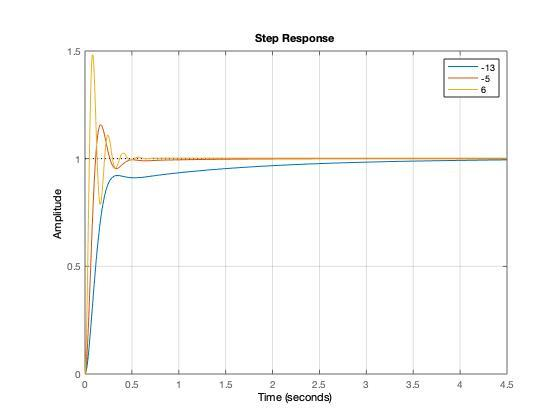

## Projeto do controlador PD via gráfico de Bode

O controlador PD é dado por $G_c(s)=K_p+K_ds=K_p(1+\frac{K_d}{K_p}s)$, ou seja, um zero é adicionado em $s=-\frac{K_{p}}{K_d}$.

O ganho proporcional pode ser utilizado para atender a especificação de erro em regime, caso este controlador seja usado sozinho. 

Neste caso, para que seja realizável, um polo deve ser adicionado, que tem a função de filtro, $G_c(s)=K_p+K_d\frac{s}{T_fs+1}$. 

Por se tratar de um zero, seu efeito nas curvas de módulo e fase do gráfico de Bode são mostrados abaixo.

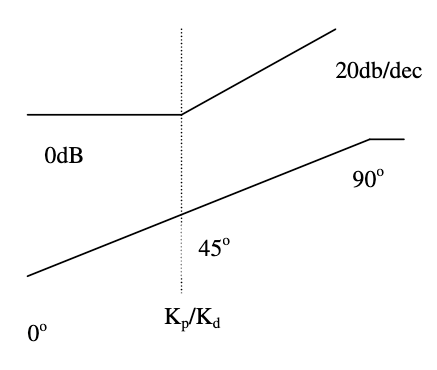

A partir da frequência do zero do PD, o módulo começa aumentar 20dB/década. Nesta frequência, a fase já avançou 45°.

Se o zero for colocado em $\omega_g^{'}$, o módulo não subirá nesta freqüência e a fase subirá 45°, aumentando a margem de fase. Logo, variações em torno desta freqüência permitirão obter a melhor MF possível. 

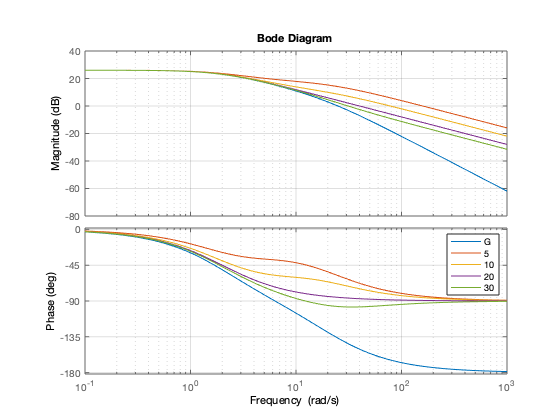

c0=tf([1/5 1],1);c1=tf([1/10 1],1); c2=tf([1/20 1],1);c3=tf([1/30 1],1);
figure;
bode(G,c0*G,c1*G,c2*G,c3*G);grid
legend('G','5','10','20','30');

No gráfico abaixo estão marcadas as margens de fase conseguidas em cada caso.

		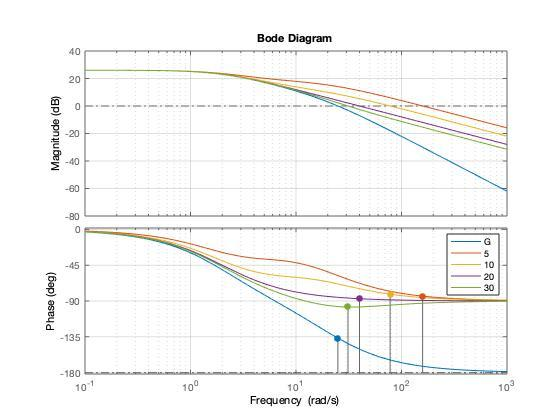	

Neste gráfico de Bode  se observa que o zero adicionado em 10rad/s permitiu a maior margem de fase, sendo que a frequência de cruzamento por 0dB do gráfico original era $\omega_g=25rad/s$.   Seu efeito depende da inclinação da curva de módulo perto de $\omega_g$.

Portanto, a referência para a localização do zero é $\omega_g$. 

**Função projpd.**

[ c, mf ] =projpd( g, f )

Argumentos de estrada são a FT g e a frequência f (em rad/s) onde se deseja inserir o zero do PD, $s=-\frac{1}{K_d}$.

A função retorna o compensador c e a margem de fase conseguida.

Usando o comando projpd(g,  [5 10 20 30]) o zero é adicionado em todas estas frequências.

usando [ c, mf ] =projpd( g) pode-se escolher a frequência f clicando no gráfico de Bode mostrado.

Voltamos agora ao projeto do controlador PI, que resultou no controlador $G_c(s)=2+\frac{8}{s}$, embora com sobreelevação de 50% aproximadamente. Vamos incluir neste projeto o efeito do PD, com ganho proporcional do PD igual a 1, ou seja, usando apenas o ganho $K_d.$ Portanto, o zero é colocado em $s=-\frac{1}{K_d}$. Vamos começar com seu gráfico de Bode:

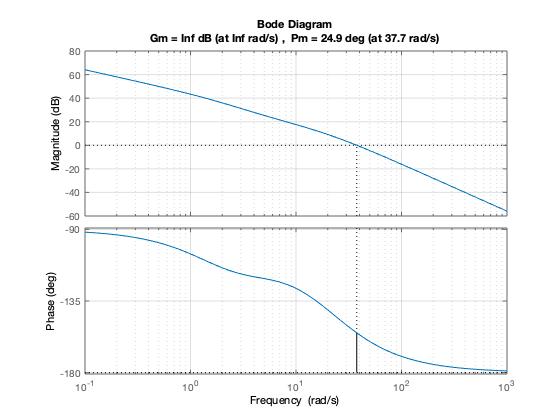

Kp=2;
Ki=8;
c1=tf([Kp Ki],[1 0]);
margin(c1*G);grid

Vamos aumentar a margem de fase de sistema com o controlador PD colocando um zero torno de $\omega_g=40rad/s$, ou seja, $\frac{1}{K_d}=40,$      Escolheremos $K_d=1/20=0.05$. Logo, o controlador PID será

Kd=1/20;
c2=pid(Kp+Kd*Ki,Ki,Kd*Kp)


c2 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 2.4, Ki = 8, Kd = 0.1
 
Continuous-time PID controller in parallel form.



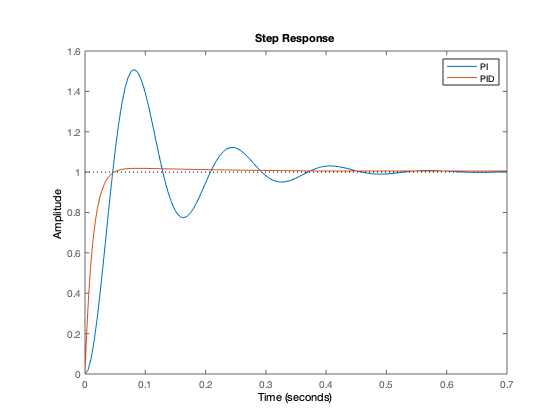

m1=feedback(c1*G,1);
m2=feedback(c2*G,1);
figure;step(m1,m2);legend('PI','PID');

A resposta obtida foi rápida, ts=0.15s, com sobreelevação de 2% em erro nulo para entrada degrau.

O gráfico de Bode é mostrado abaixo. A margem de fase passou de 29 graus com PI para 90 graus com o PID.

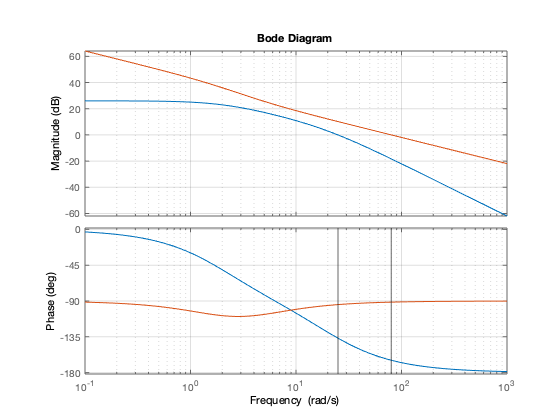

figure;
bode(G,c2*G);grid
xline(25);xline(80);

**Usando as funções projpi e projpd para este exemplo:**

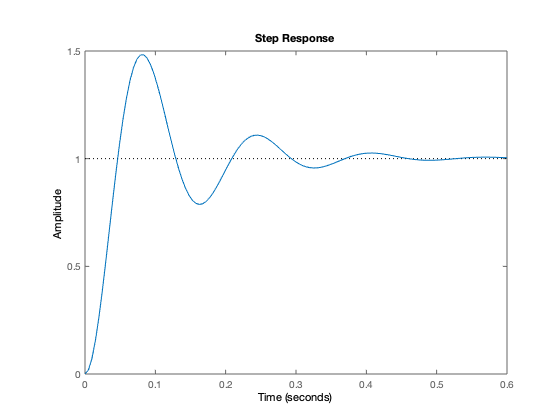

c1=projpi(G,6);
figure;
step(feedback(c1*G,1));

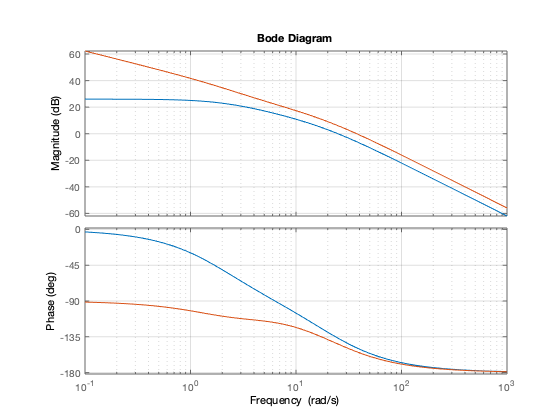

figure;
bode(G,c1*G);grid;

Adicionando o zero em $\omega=20rad/s$

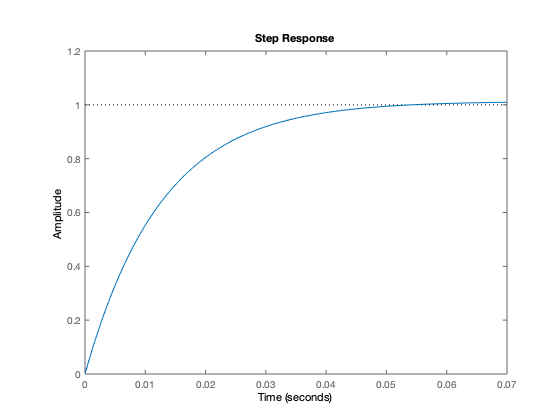

c2=projpd(c1*G,20);
C=c1*c2;
figure;step(feedback(C*G,1));

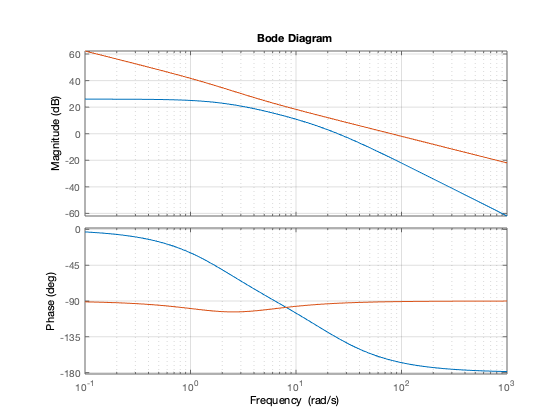

figure;bode(G,C*G);grid;

**Exercício**: projetar um controlador PI ou PID para $G(s)=\frac{100}{(s+1)(s+2)(s+10)}$

atendendo as especificações:


$$UP\leq4.3%$$



$$ts\leq 2$$


Erro à entrada degrau < 1%.

Ganho de K de g(s):

g=tf(100,poly([-1 -2 -10]));

K = 5

K=freqresp(g,0)

Para atender o erro em regime sem aumentar o tipo, é preciso que o controlador tenha um ganho $\geq20$.

Vamos projetar Inicialmente um PI para atender ao erro em regime.

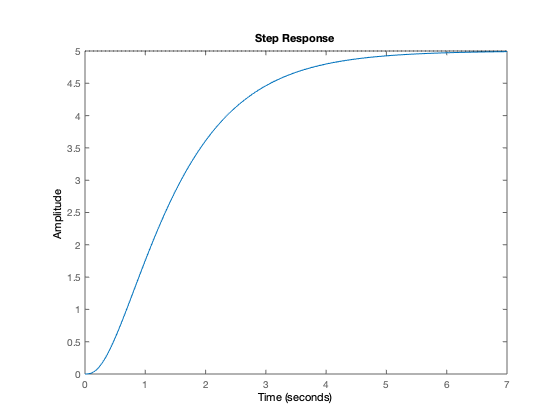

g=tf(100,poly(-[1 2 10]));
figure;step(g);

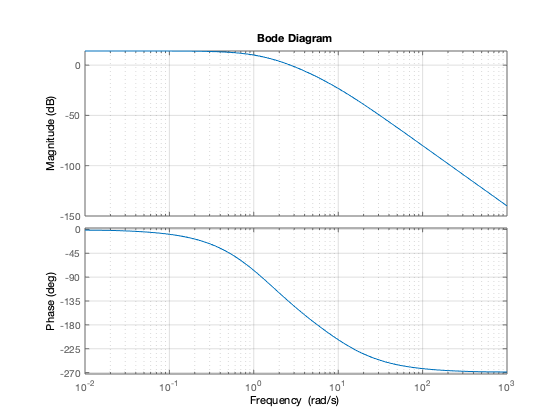

figure;bode(g);grid

Vamos escolher um ganho maior do que um para uma resposta mais rápida. O ganho deve aumentar 2dB (ganho 1.25). a curva de módulo sobre 2dB,cruzando por 0dB em 3rad/s. O zero do PI é colocado 1 década antes, ou seja, em 0.3rad/s,

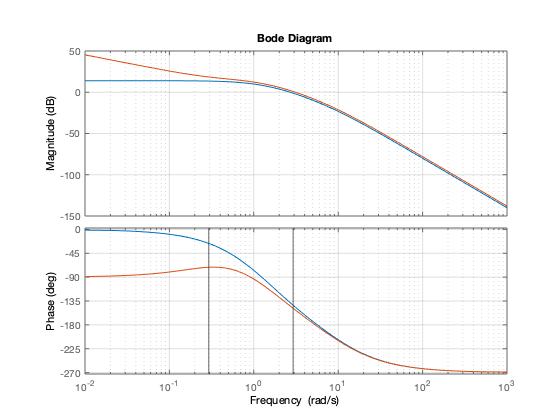

[c1,wg]=projpi(g,2);
figure;bode(g,c1*g);grid;xline(wg/10);xline(wg);

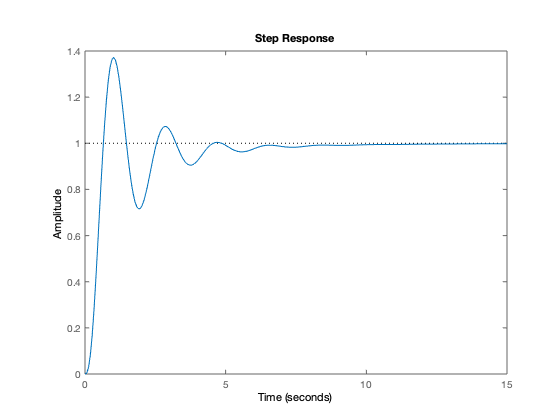

m=feedback(c1*g,1);
figure;step(m);

Fazemos agora o projeto do controlador PD para reduzir a sobreelevação. O zero do PD é adicionado em 7rad/s.

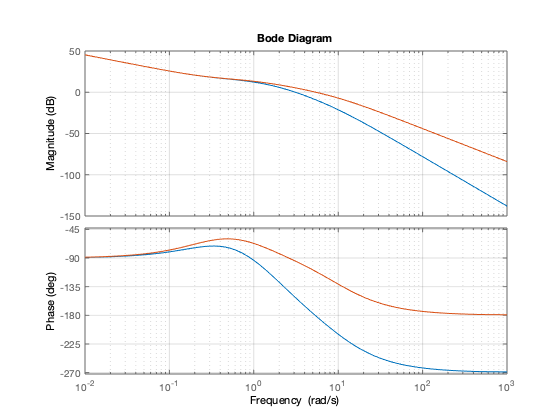

c2=projpd(c1*g,2);
figure;bode(c1*g,c1*c2*g);grid;

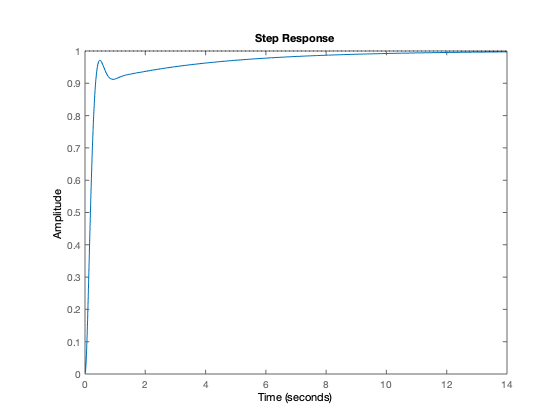

m=feedback(c1*c2*g,1);
figure;step(m);

Atenção:

Seja agora o mesmo valor de Kp=1.28, o mesmo valor de Kd=0.47, porém trocando Ki=0.36 do projeto por Ki=0.86, ou seja

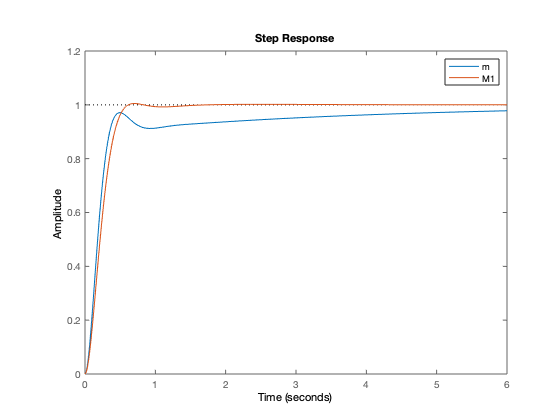

C1x=pid(1.28, 0.86, 0.47);
M1=feedback(C1x*g,1);
figure;step(m,M1,6);legend('m','M1');

O novo controlador tem desempenho melhor que o projetado via Bode, conseguindo atender $t_s<2s$.

**Conclusão: os métodos de projeto podem apresentar limitações que impeçam um melhor projeto, dada sua metodologia.**